# Navigate Global Path Through Offroad Terrain Using Local Planner

This example shows how to use the timed elastic band (TEB) controller as a local planner that navigates planned network paths while conforming to the kinematic and geometric constraints of the haul truck. The example uses the road network path planner and road network derived from terrain data in the [Create Route Planner for Offroad Navigation Using Digital Elevation Data](matlab:open('./CreateRoutePlannerUsingDigitalElevationData.mlx')) example, and the terrain-aware global planner for entering and exiting that road network developed in the [Create Onramp and Terrain-Aware Global Planners for Offroad Navigation](matlab:open('./CreateTerrainAwareGlobalPlanners.mlx')) example.

## Load Terrain, Road Network, and Planner Parameter Data

Load the terrain data, road network paths, and planner parameters into the workspace.

load("OpenPitMinePart1Data.mat","dem","pathList")              % Terrain and road network
load("OpenPitMinePart2Data.mat","originalReferencePath", ...   % Planned road network path
                                "smoothedReferencePath", ...   % Smoothed road network path
                                "fixedTerrainAwareParams", ... % Fixed terrain-aware parameters
                                "tuneableTerrainAwareParams")  % Tunable terrain-aware parameters

Use the `exampleHelperDem2mapLayers` helper function to convert the digital elevation data into a cost map.

[costMap,maxSlope] = exampleHelperDem2mapLayers(dem,tuneableTerrainAwareParams.MaxAngle,fixedTerrainAwareParams.Resolution);
obstacles = getLayer(costMap,"terrainObstacles");

## Create TEB Local Planner

While following the reference paths on the road network, the haul truck must be able to avoid collisions and stay as close to the reference paths as possible. To ensure this, you can use a timed elastic band (TEB) controller as a local planner. The TEB controller dynamically optimizes the trajectory of the haul truck by considering both the geometry and kinematic constraints of the vehicle, as well as the presence of obstacles. 

To create a TEB controller, you must first define the parameters that describe the geometry and the kinematic constraints of the haul truck. The geometry parameters and kinematic constraints align with the two parameter categories used in the [Create Terrain-Aware Global Planners for Offroad Navigation](matlab:open('./CreateTerrainAwareGlobalPlanners.mlx')) example: those expected to stay constant during vehicle operation and those expected to change, respectively. Categorizing the parameters this way enables you to more easily incorporate your planning modules into a Simulink® model, as the separation aligns with how Simulink makes constant parameters accessible through block masks and accepts tunable parameters as Simulink bus signals.

Initialize the parameters for the local planner using the `exampleHelperTEBParams` example function. Note that you must keep the network planner parameters when setting the local planner parameters. For instance, you might choose the same minimum turning radius value for both planners, or opt for a larger radius in the network planner, to ensure that the local controller can follow the planned path more efficiently. This structured approach allows the TEB controller to efficiently compute feasible and collision-free trajectories that the haul truck can follow in real-time, ensuring both obstacle avoidance and adherence to the reference paths.

[tunableTEBParams,fixedTEBParams] = exampleHelperTEBParams

tunableTEBParams = struct with fields:
           LookaheadTime: 6
    ObstacleSafetyMargin: 1
             CostWeights: [1×1 struct]
        MinTurningRadius: 17.2000
             MaxVelocity: [16 0.9302]
         MaxAcceleration: [0.6000 0.1000]
      MaxReverseVelocity: 8


fixedTEBParams = struct with fields:
                Length: 6.5000
                 Width: 5.7600
          NumIteration: 3
    ReferenceDeltaTime: 0.2000
      RobotInformation: [1×1 struct]


Initialize the vehicle dimensions using the defined parameters, and set up a collision checker with a specified inflation radius expanded from those dimensions.

vehDims = exampleHelperVehicleGeometry(fixedTEBParams.Length,fixedTEBParams.Width,"collisionChecker")
collisionChecker = inflationCollisionChecker(vehDims,3);

To ensure the local planner can navigate the planned paths in the road network, inflate the road network by using the `exampleHelperInflateRoadNetwork` helper function.

exampleHelperInflateRoadNetwork(obstacles,pathList,collisionChecker.InflationRadius*1.5)

Create a local ego map that covers only the area accessible to the the haul truck within one planning iteration of the local planner. This reduces the computational load required for the local planner to identify nearby obstacles, and minimizes the size of map signals for smoother integration into subsequent Simulink models. 

maxDistance = (tunableTEBParams.MaxVelocity(1)*tunableTEBParams.LookaheadTime/obstacles.Resolution);
localMap = binaryOccupancyMap(2*maxDistance,2*maxDistance,obstacles.Resolution);
localMap.GridOriginInLocal = -localMap.GridSize/(2*localMap.Resolution);

Create the TEB controller as a `controllerTEB` object using the smoothed network path and local ego map. This controller acts as the local planner. Then customize the controller parameters using the predefined properties.

teb = controllerTEB(smoothedReferencePath,localMap);
teb.CostWeights.Time       = tunableTEBParams.CostWeights.Time;
teb.CostWeights.Smoothness = tunableTEBParams.CostWeights.Smoothness;
teb.CostWeights.Obstacle   = tunableTEBParams.CostWeights.Obstacle;
teb.RobotInformation       = fixedTEBParams.RobotInformation;
teb.MinTurningRadius       = tunableTEBParams.MinTurningRadius;
teb.ObstacleSafetyMargin   = collisionChecker.InflationRadius*2;
teb.NumIteration           = fixedTEBParams.NumIteration;
teb.MaxVelocity            = tunableTEBParams.MaxVelocity;
teb.MaxReverseVelocity     = tunableTEBParams.MaxReverseVelocity;
teb.MaxAcceleration        = tunableTEBParams.MaxAcceleration;
teb.ReferenceDeltaTime     = fixedTEBParams.ReferenceDeltaTime;
teb.LookAheadTime          = tunableTEBParams.LookaheadTime; % In seconds

## Handling `controllerTEB` Exit Flags

When performing optimization, solvers can encounter issues like local minima and soft constraint violations, or might not converge. The [`controllerTEB`](https://www.mathworks.com/help/nav/ref/controllerteb.html) object provides error codes to identify these problems. These are some of the failure modes the controller might experience during simulation, and their corresponding causes and countermeasures:

### Minimum Turning Radius Violated by More Than 10%

If the optimized path causes the vehicle to exceed the minimum turning radius by more than 10%, indicated by an `ExitFlag` value of `3`, the vehicle might have difficulty adhering to the designated optimized path. This discrepancy often comes from a misalignment between the actual orientation of the vehicle and the trajectory planned by the optimizer. In an attempt to correct this misalignment and closely follow the planned path, the optimizer might inadvertently surpass the kinematic limits of the vehicle, resulting in commands that are not realistically executable. To mitigate this issue, you can set a cap on the control commands to ensure they do not exceed the minimum turning radius of the vehicle. Although this approach might cause the vehicle to deviate slightly from the intended optimal route, it prevents the system from being trapped in scenarios of local minima, ensuring smoother navigation.

This figure shows an example of a vehicle path with turn commands being capped to ensure that the vehicle does not exceed the minimum turning radius, at the cost of deviating from the reference path.

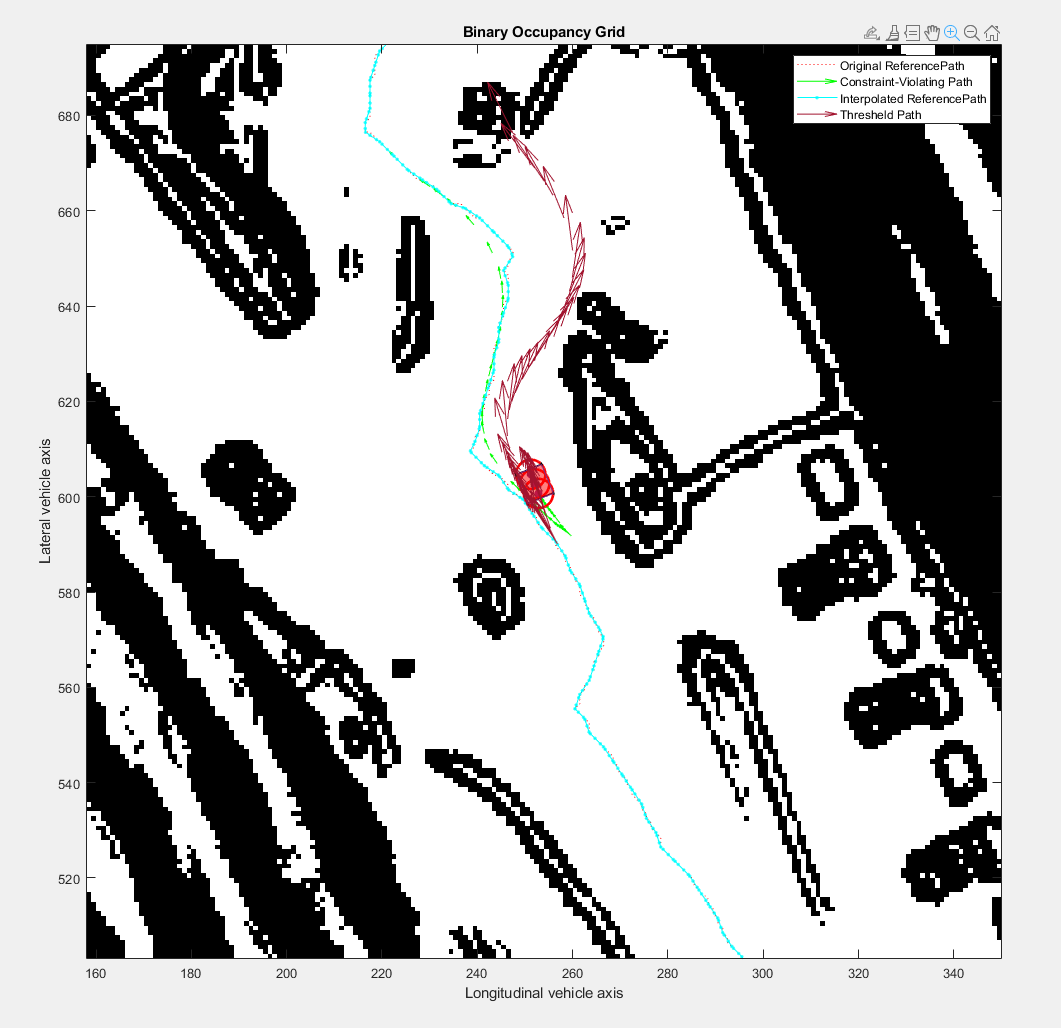

### Obstacle Safety Margin Violated by More Than 10%

If the optimized path causes the vehicle causes the vehicle to exceed the obstacle safety margin by more than 10%, indicated by an `ExitFlag` value of `2`, it suggests that the optimized path might be prone to collisions. The TEB controller typically raises this flag when the reference path is navigating through a particularly tight corridor, or the specified safety margin is significantly larger than the actual dimensions of the vehicle. Because the obstacle safety margin essentially acts as an additional buffer around the vehicle, you must to determine whether an obstacle-constraint violation actually indicates a collision or just an encroachment upon this buffer zone. If the violation affects only the padding without impacting the vehicle, you might be able to safely disregard the violation, as it does not result in an actual collision.

This figure shows an example of the haul truck following the reference path, while avoiding the red obstacle safety margin.

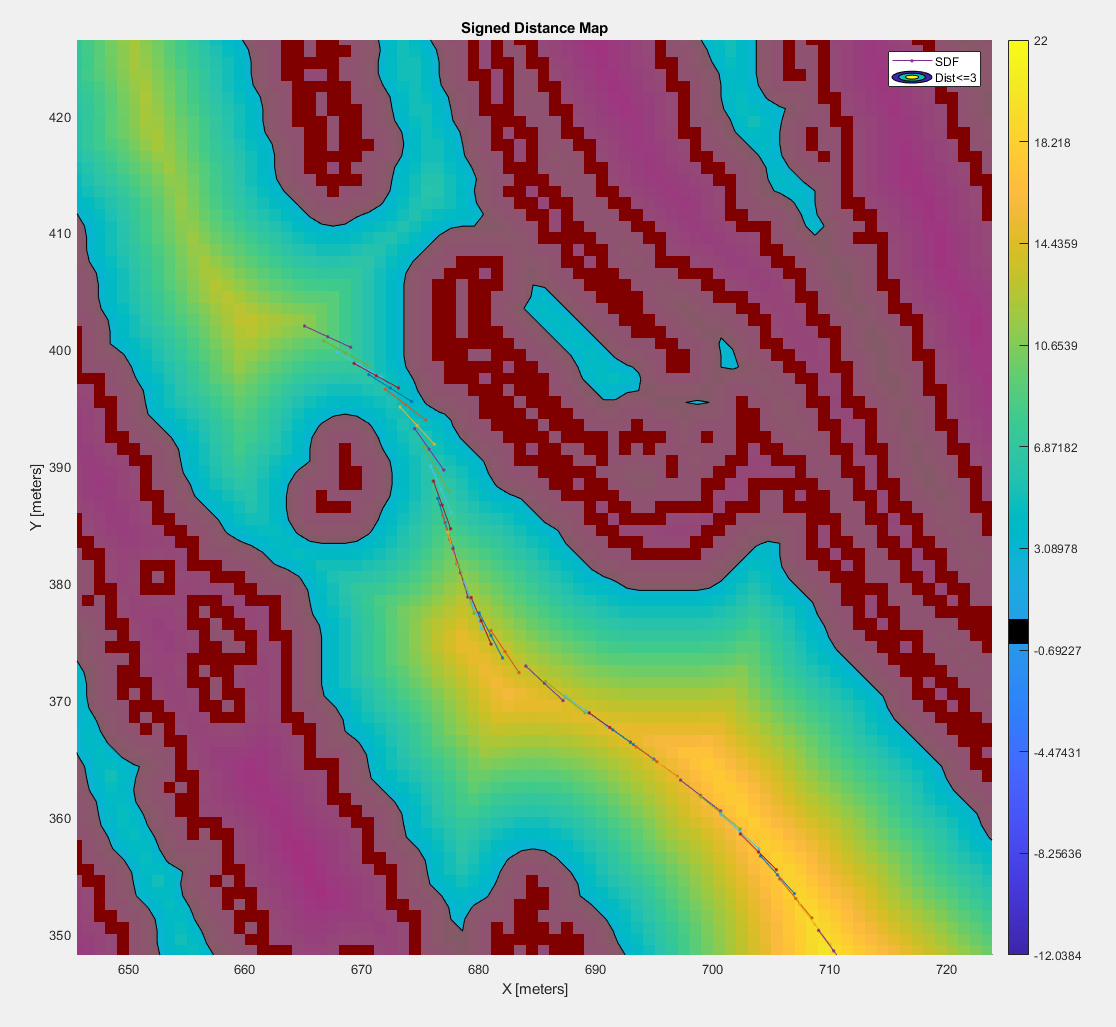

### Path Planning Fails Due to Unreachable Points or Local Minima

Situations where the TEB controller fails to generate an output, or outputs that the last feasible index is the first state (`LastFeasibleIdx == 1`), often indicate that the controller got stuck in a local minima, or that nearby reference path points are unreachable. Such issues typically occur during a local replan triggered by the vehicle moving parallel to the reference path or facing rapid directional changes. In this case, traveling to these nearest points is not feasible as they lie within the minimum turning radius of the vehicle, requiring the haul truck to violate its kinematic constraints to reach them. To address this issue, remove the unreachable points and initiate a local replan by using the `exampleHelperProcessTEBErrorCodes` function. After a second failed attempt at local replanning, the function advises a global replan to circumvent the planning issue.

This figure shows an example of the vehicle traveling parallel to the reference path. The red lookahead points on the reference path are invalid because they lie within the unreachable minimum turning radius region, even though they are the closest lookahead points. The blue points are the valid next lookahead points.

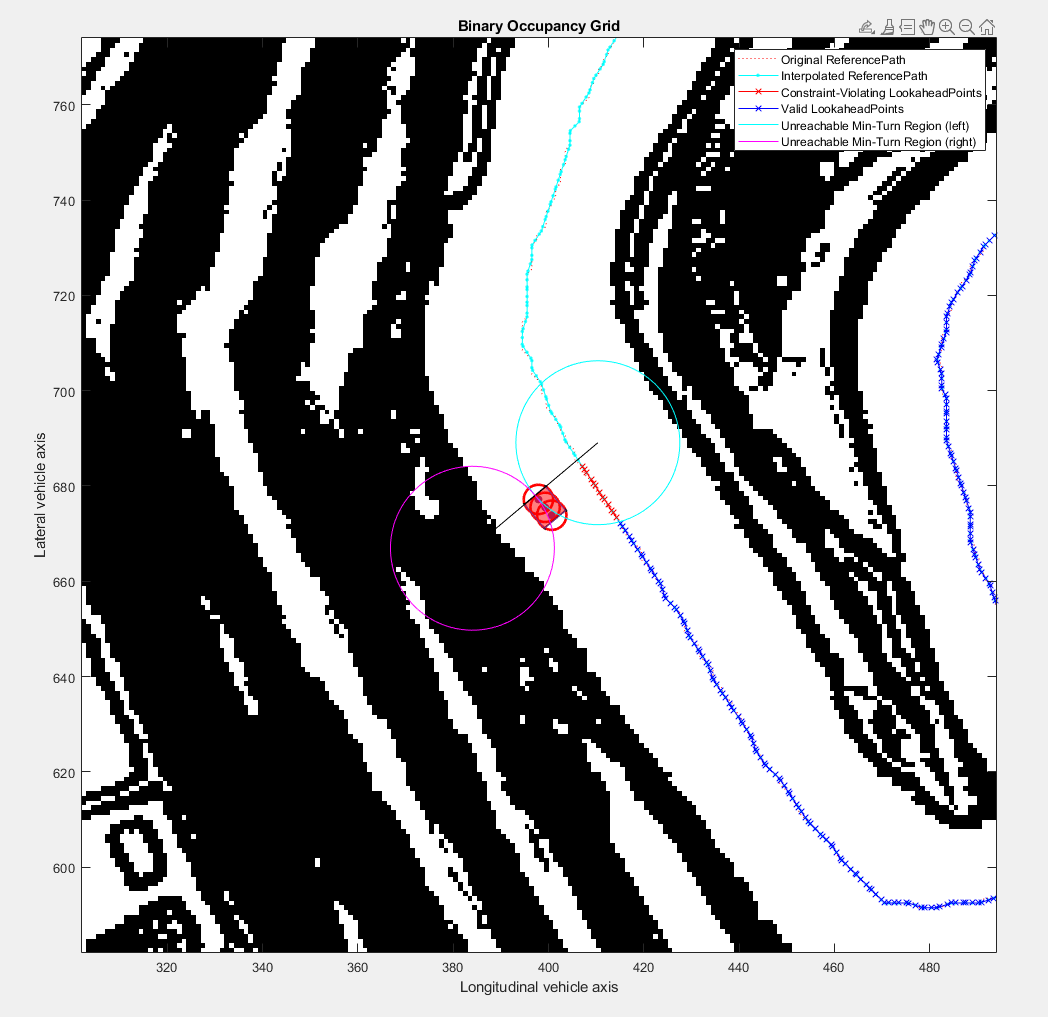

**Note:** These failure conditions are not exhaustive, and the remedies described do not represent complete solutions, but demonstrate that you can use the `controllerTEB` error codes to reason through and work around edge-cases caught while prototyping.

## Simulate Haul Truck Following Reference Path

Simulate the `controllerTEB` outputs driving the haul truck along the reference path. The local planner generates a timestamped sequence of `[velocity angularVelocity]` control commands, and then the simulation integrates those commands to update the state of the haul truck.

### Set Up Simulation Parameters

Initialize the parameters that you need for the simulation, such as the visualization interval and integration step size.

%% Follow path and visualize
teb.ReferencePath = smoothedReferencePath; % Reference path
curpose = smoothedReferencePath(1,:);      % Current pose as first point in reference path
curvel = [0 0];                            % Current linear and angular velocity
simtime = 0;                               % Current simulation time starting at 0
tsReplan = 3;                              % Interval between replanning in seconds
tsIntegrator = 0.001;                      % Integration step size in seconds
tsVisualize = 0.1;                         % Visualization interval in seconds
itr = 0;                                   % Iteration counter
goalReached = false;                       % Flag for goal status
tVis = inf;                                % Time since last visualization
tPlan = inf;                               % Time since last planning
adjustedPath = 0;                          % Counter or flag for adjusted paths

### Run Simulation

Set up the figures for the visualization.

figure
show(obstacles)
hold on
exampleHelperPlotLines(teb.ReferencePath,{"MarkerSize",10})
hTEBPath1_1 = quiver(nan,nan,nan,nan,.2,DisplayName="Current Path",LineWidth=3);

figure
move(localMap,curpose(1:2),MoveType="Absolute");
syncWith(localMap,obstacles);
h = show(localMap);
ax2 = h.Parent;
title("Simulation of Haul Truck Following Path")
hold on

Plot the original and smoothed reference paths.

exampleHelperPose2Quiver(originalReferencePath,{"AutoScale","off"})
exampleHelperPose2Quiver(smoothedReferencePath,{"AutoScale","off"})

Initialize visualization for the `controllerTEB` path.

hRef = exampleHelperPlotLines(teb.ReferencePath,{"MarkerSize",10});
hTEBPath1_2 = quiver(nan,nan,nan,nan,.2,DisplayName="Current Path");
[~,hVeh] = exampleHelperCreateVehicleGraphic(gca,"Start",collisionChecker);
hTEBPath2_2 = hgtransform;
arrayfun(@(x)set(x,"Parent",hTEBPath2_2),hVeh)
hRefCur = exampleHelperPlotLines(teb.ReferencePath,".-");

To simulate and visualize the path-following behavior of a haul truck using the TEB controller, follow these steps:

- Update the local map and the state of the haul truck based on sensor inputs or global map information.

- Periodically replan the path based on the current state of the haul truck, and visualize the updates.

- Integrate the motion model of the haul truck over time to simulate movement.

- End the simulation once the vehicle reaches the goal or meets a termination condition, such as encountering a local minima, that requires a new reference path.

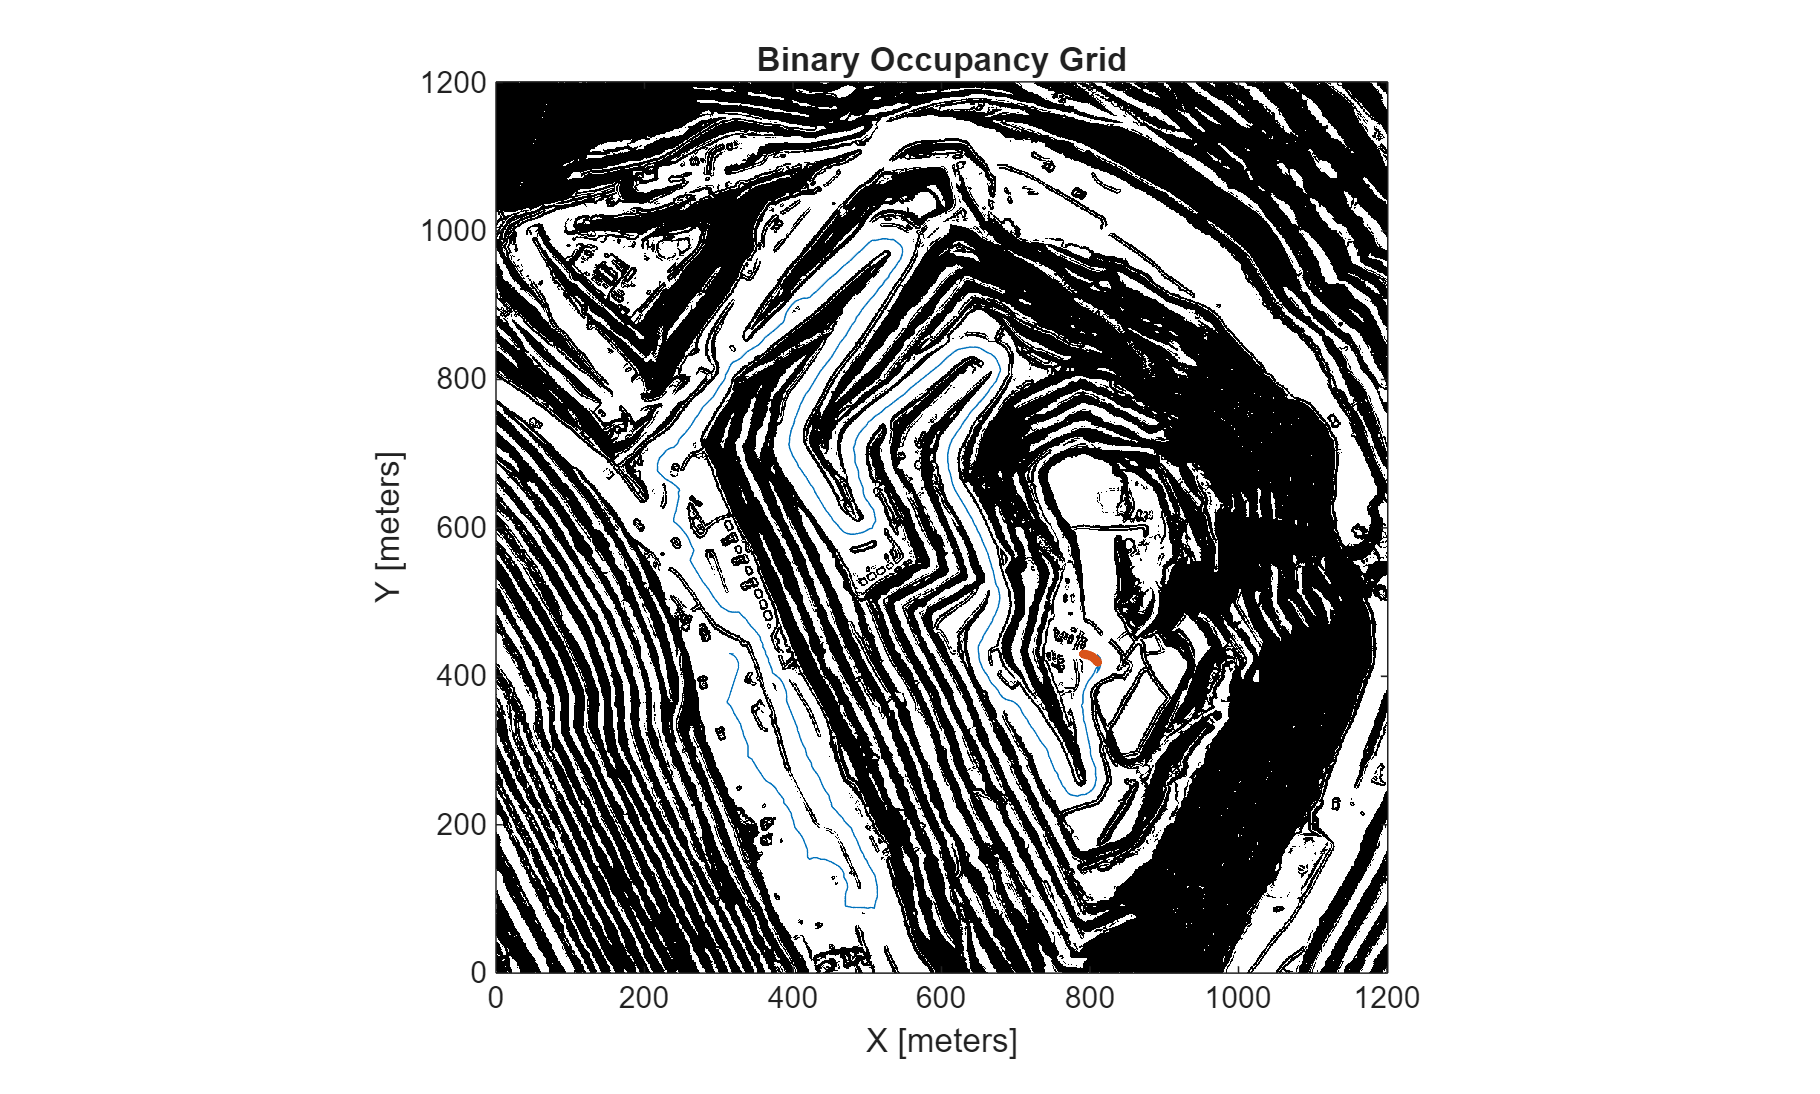

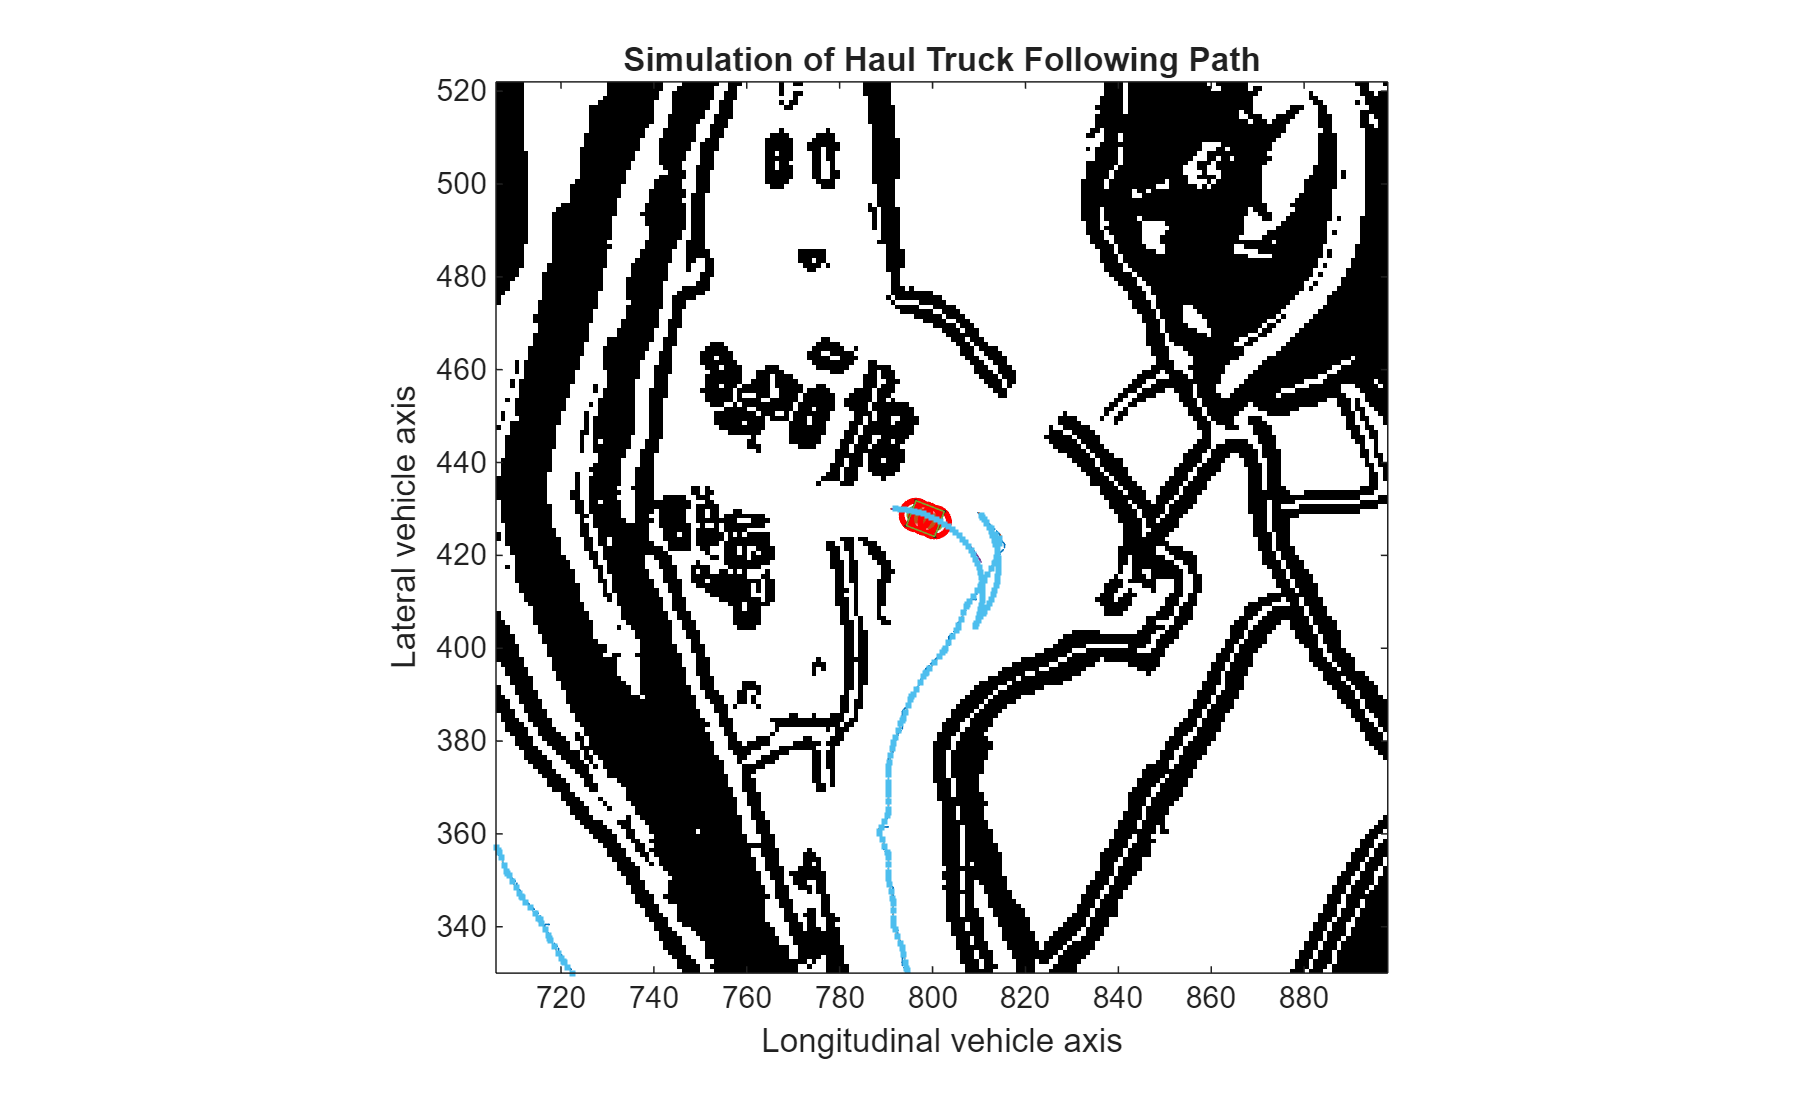

% Simulate until haul truck is within 10 meters of the final goal position
while norm(curpose(1:2)-smoothedReferencePath(end,1:2),2) > 10

    % Update visualization and local map if time since the last
    % visualization update exceeds the visualization interval
    if tVis >= tsVisualize
        move(localMap,curpose(1:2),MoveType="absolute",SyncWith=obstacles);
        show(localMap,Parent=ax2,FastUpdate=1);
        hTEBPath2_2.Matrix(1:3,:) = [eul2rotm([0 0 curpose(3)],"XYZ") [curpose(1:2)';0]];
        drawnow limitrate;
        tVis = 0;
    end

    % Replan and update path of vehicle if time since last replanning
    % exceeds replanning time interval
    if tPlan >= tsReplan

        % Update local map
        move(localMap,curpose(1:2),MoveType="absolute",SyncWith=obstacles);
        
        % Generate new velocity commands with TEB controller
        [velcmds,tstamps,curpath,info] = teb(curpose,curvel);
        
        % End simulation if goal is reached
        if info.HasReachedGoal
            break
        end
        
        % Update TEB path visualization with new state information
        set(hTEBPath1_1,XData=curpath(:,1), ...
                        YData=curpath(:,2), ...
                        UData=cos(curpath(:,3)), ...
                        VData=sin(curpath(:,3)))
        set(hTEBPath1_2,XData=curpath(:,1), ...
                        YData=curpath(:,2), ...
                        UData=cos(curpath(:,3)), ...
                        VData=sin(curpath(:,3)));
        set(hRefCur,XData=teb.ReferencePath(:,1), ...
                    YData=teb.ReferencePath(:,2))
        hTEBPath2_2.Matrix(1:3,:) = [eul2rotm([0 0 curpose(3)],"XYZ") [curpose(1:2)'; 0]];
        
        % Handle TEB error codes, and adjust path if necessary
        [velcmds,tstamps,curpath,adjustedPath,needLocalReplan,needFreeSpaceReplan] = ...
            exampleHelperProcessTEBErrorCodes(teb,curpose,curvel,velcmds,tstamps,curpath,info,adjustedPath, ...
            teb.RobotInformation.Dimension(1),teb.RobotInformation.Dimension(2));

        % Determine replanning requirements
        if needLocalReplan
            % Local adjustments required, skip to next iteration for replanning
            continue
        else 
            if needFreeSpaceReplan
                % Critical issue, requires complete replanning
                error("Need replan")
            end
        end

        % Update simulation and visualization timestamps
        timestamps = tstamps + simtime;
        
        tVis = 0;
        tPlan = 0;
    end
    
    % Reset the adjustedPath flag for next iteration whenever TEB is
    % successful or results can be corrected.
    adjustedPath = 0;

    % Integrate the motion model
    simtime = simtime + tsIntegrator;
    tVis = tVis + tsIntegrator;
    tPlan = tPlan + tsIntegrator;

    % Compute the instantaneous velocity command to send to robot
    velcmd = velocityCommand(velcmds,timestamps,simtime);
    
    % Integrate the velocity command to find change in state
    statedot = [velcmd(1)*cos(curpose(3)) ...    % x-dot
                velcmd(1)*sin(curpose(3)) ...    % y-dot
                velcmd(2)];                      % theta-dot

    % Update current pose using the change in state
    curpose = curpose + statedot*tsIntegrator;

    % Update current velocity to the velocity command
    curvel = velcmd;
end

## Conclusion

In this example you implemented a local path follower using the `controllerTEB` object. This TEB controller processed a previously defined reference path, enabling you to plan control commands to guide a vehicle along the reference path while avoiding obstacles.

You also explored several challenges commonly faced by optimization-based planners, and practiced troubleshooting and resolving such complications. Lastly, you simulated the haul truck following your planned path, and visualized the results.

Next you can create a model predictive control (MPC) based controller for handling the vehicle control, as described in [Create Path Following MPC Controller](matlab:open('./CreatePathFollowingMPCController.mlx')).

*Copyright 2023-2024 The MathWorks, Inc.*